# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

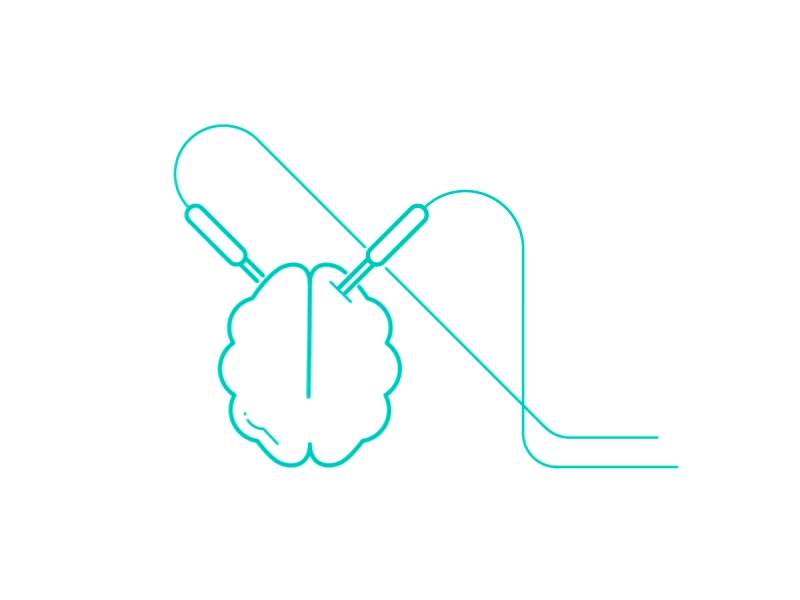

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Vighnesh\Data\MSIT\RawData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                                  % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\Vighnesh\Data\MSIT\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {5};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {6};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[22:25] [37:39] [42:44]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [10 20 30 69 40 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Block.Start   = {3};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {4};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)

## 2. PreProcessing Steps

Deci.PP.HBP        = 1;                                                                         % Scalar,High-bandpass filter, in Hz.
Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []                                                                         % Add additionall Preprocessing Parameters as according to ft_preprocessing

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 5
        Proceed: 0
           PCom: 0
             DT: [1×1 struct]
             PP: [1×1 struct]


## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];                                                                % Critical Time Period for trial rejection (Respective to first Lock and Last Lock)
Deci.Art.muscle     = [];                                                                       % if empty, use default muscle parameters
Deci.Art.eog        = [];                                                                       % if empty, use default eog parameters
Deci.Art.PostICAbpf = [];                                                                       % Post ICA broadband pass filter, if desired

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace       =true;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.Locks         = [1 2 3 4 5 6];                                                          % Which Lock to Analyze        
Deci.Analysis.LocksTitle    = {'Spatial Stim Onset', 'MSIT Stim Onset', 'MSIT Response Onset', 'Spatial Response Onset','MSIT Fdb Onset', 'Spatial Fdb Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.DownSample    = 500;                                              % Downsample Pre-Analysis
Deci.Analysis.Conditions    = {[22 43] [23 43] [24 43] [25 43] [22 44] [23 44] [24 44] [25 44]};
Deci.Analysis.CondTitle     = {'null_corr' 'cong_corr' 'lo_corr' 'hi_corr' 'null_incorr' 'cong_incorr' 'lo_incorr' 'hi_incorr'};

#### Time-Frequency Analysis

Deci.Analysis.Freq.do            = true;
Deci.Analysis.Freq.method        = 'wavelet';                                                  % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));                           % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;                                                         % Width
Deci.Analysis.Freq.gwidth        = 3;                                                          % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];                                                  % Time Range to save
Deci.Analysis.Freq.Toilim        = [-2 3];                                                     % Time Range to do freq analysis on


#### Cross-Frequency Coupling

% Currently Unavailable
Deci.Analysis.CFC.do = false;
Deci.Analysis.CFC.chanlow =  {'FCz'};
Deci.Analysis.CFC.chanhigh = {'CP3'};
Deci.Analysis.CFC.latencyhigh = [-.2 1];                                                        %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-.2 1];
Deci.Analysis.CFC.freqhigh = 'theta';
Deci.Analysis.CFC.freqlow = 'beta';
Deci.Analysis.CFC.timebin = 6;
Deci.Analysis.CFC.methods = {'mi' 'plv'};                                                       % can only currently handle '' or 'mi'(pac)

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];

## 5. Plotting

**General Set-Up**

Deci.Plot.Lock         = 'MSIT Stim Onset';                   % Which Lock to load                 
Deci.Plot.GrandAverage = false;                                   % Whether or not to grandaverage
Deci.Plot.FreqYScale   = 'linear';                   % Is the Frequency Y scale for Square plots on a linear or log scale?

% Comment your CondTitles here so you can refer to them for Math and Draw
Deci.Plot.IndexTitle     = {'null_corr' 'cong_corr' 'lo_corr' 'hi_corr' 'null_incorr' 'cong_incorr' 'lo_incorr' 'hi_incorr'};

Deci.Plot.Math         = {'[x4-x2]','[x8-x6]','[x3-x2]','[x7-x6]', '[x5+x6+x7+x8]-[x1+x2+x3+x4]'};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1:4] [5:8] [9:12] [13]};                   % Cell array of Condition Index for each figure
Deci.Plot.Figures      = [true true true true];                             % Which figure to plot currently
Deci.Plot.Title        = {'correct trials' 'IC trials' 'Int-Cong' 'IC-C'};          % Title for each figure
Deci.Plot.Subtitle     = {{'null_corr' 'cong_corr' 'lo_corr' 'hi_corr'} {'null_incorr' 'cong_incorr' 'lo_incorr' 'hi_incorr'} {'hi_corr-cong_corr' 'hi_incorr-cong_incorr' 'lo_corr-cong_corr' 'lo_incorr-cong_incorr'} {'IC-C'}};     % Cell array of strings of subtitles for each Condition

#### Time-Frequency

Deci.Plot.Freq.Foi     = [8 12];                   % Frequency of Interest
Deci.Plot.Freq.Toi     = [];                   % Time of Interest
Deci.Plot.Freq.Channel = ['Reinhart-All'];                   % Channel of Interest
Deci.Plot.Freq.Type    = 'TotalPower';                   % Use 'TotalPower','ITPC' or 'EvokedPower' (Currently Unavailable)
Deci.Plot.Freq.Bsl     = [-.5 -.2];                             % Baseline Correction Time
Deci.Plot.Freq.Topo    =true;
Deci.Plot.Freq.Square  =true;
Deci.Plot.Freq.Wire    =true;

**CFC**

%Currently Unavailable
Deci.Plot.CFC.Topo = true;
Deci.Plot.CFC.Square = true;
Deci.Plot.CFC.Hist = true;
Deci.Plot.CFC.Wire = true;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest

**ERP**

Deci.Plot.ERP.Toi = [0 .8];
Deci.Plot.ERP.Channel = {'FCz'};
Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.ERP.Topo =true;
Deci.Plot.ERP.Wires =true;

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1:16] [1:16]};
Deci.Plot.Behv.Acc.Subtotal = {[1:8] [9:16]};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent' 'All Trials Percent'};
Deci.Plot.Behv.Acc.Subtitle = {'Opt Percent' 'Wst Percent'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;

Deci.Plot.Behv.RT.Draw = {[1:8] [9:16]};
Deci.Plot.Behv.RT.Title = {'All Trials RT' 'All Trials Percent'};
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

** Extra**

Deci.Plot.Extra.List = true;
Deci.Plot.Extra.Functions = {'QL'};
Deci.Plot.Extra.Params = {{}};

**Options**

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

## ** 6. Run**

Channel AF3 of 59
Channel AF4 of 59
Channel AF7 of 59
Channel AF8 of 59
Channel AFz of 59
Channel C1 of 59
Channel C2 of 59
Channel C3 of 59
Channel C4 of 59
Channel C5 of 59
Channel C6 of 59
Channel CP1 of 59
Channel CP2 of 59
Channel CP3 of 59
Channel CP4 of 59
Channel CP5 of 59
Channel CP6 of 59
Channel CPz of 59
Channel Cz of 59
Channel F1 of 59
Channel F2 of 59
Channel F3 of 59
Channel F4 of 59
Channel F5 of 59
Channel F6 of 59
Channel F7 of 59
Channel F8 of 59
Channel FC1 of 59
Channel FC2 of 59
Channel FC3 of 59
Channel FC4 of 59
Channel FC5 of 59
Channel FC6 of 59
Channel FCz of 59
Channel FT7 of 59
Channel FT8 of 59
Channel Fz of 59
Channel O1 of 59
Channel O2 of 59
Channel Oz of 59
Channel P1 of 59
Channel P2 of 59
Channel P3 of 59
Channel P4 of 59
Channel P5 of 59
Channel P6 of 59
Channel P7 of 59
Channel P8 of 59
Channel PO3 of 59
Channel PO4 of 59
Channel PO7 of 59
Channel PO8 of 59
Channel POz of 59
Channel Pz of 59
Channel T7 of 59
Channel T8 of 59
Channel TP7 of 59
Chan

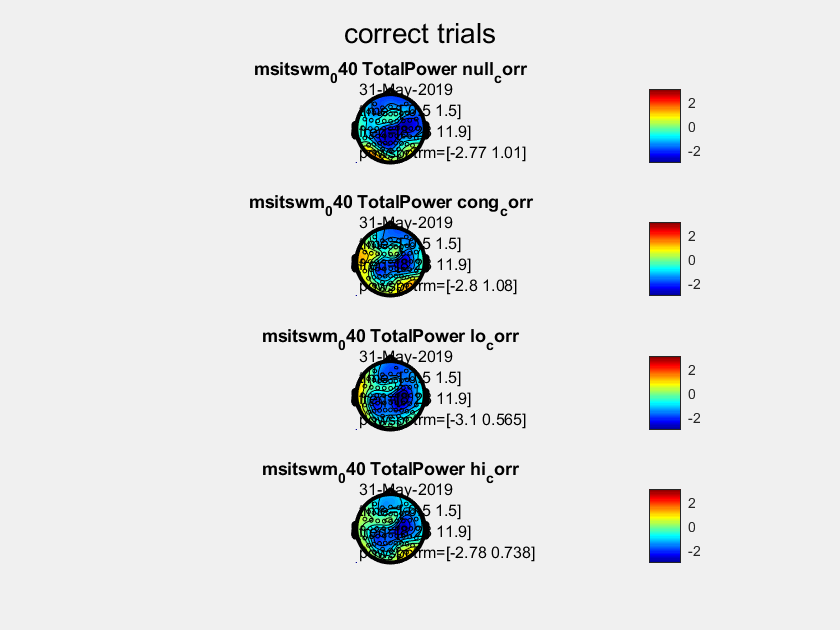

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


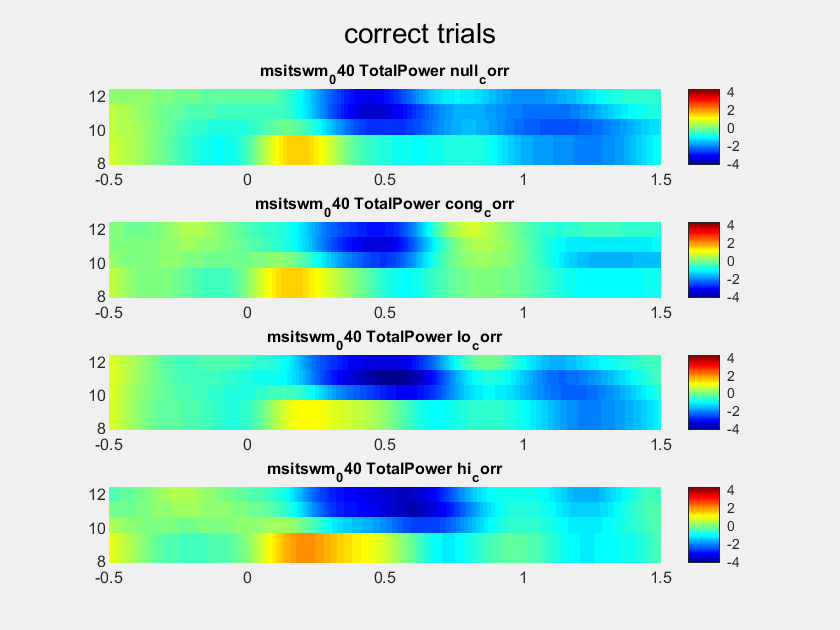

the call to "ft_singleplotTFR" took 0 seconds


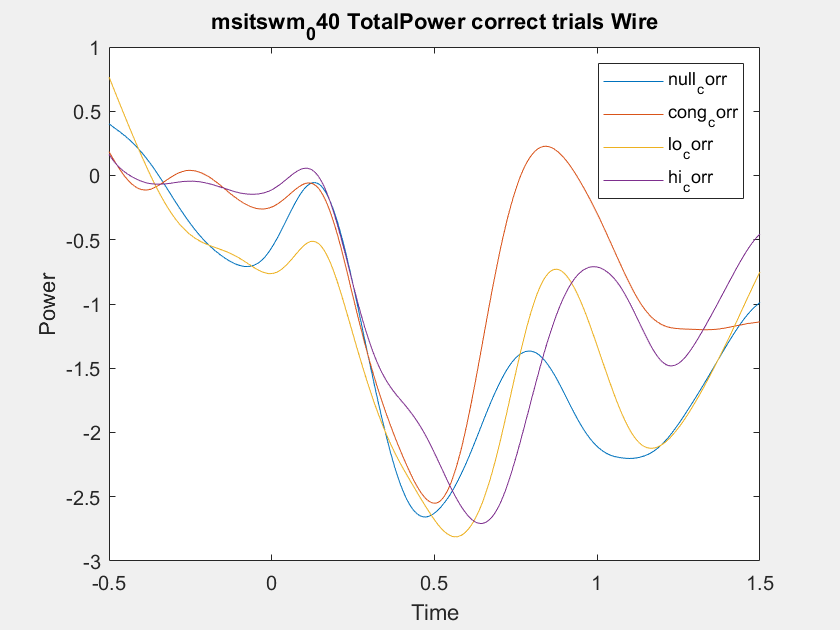

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


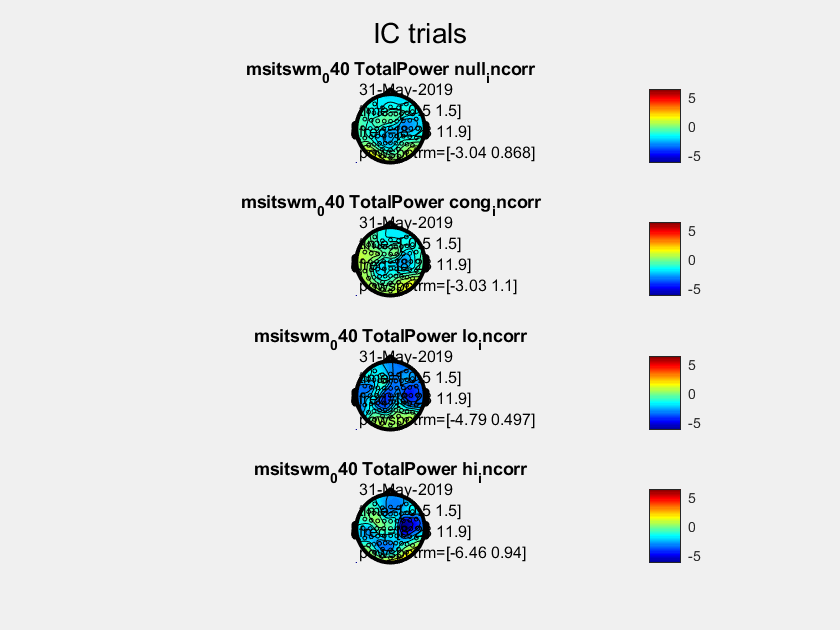

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


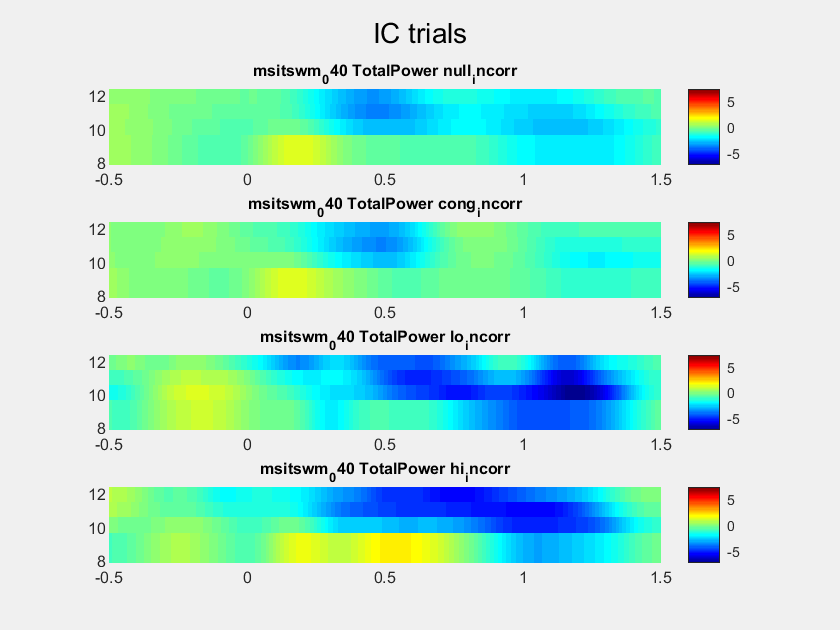

the call to "ft_singleplotTFR" took 0 seconds


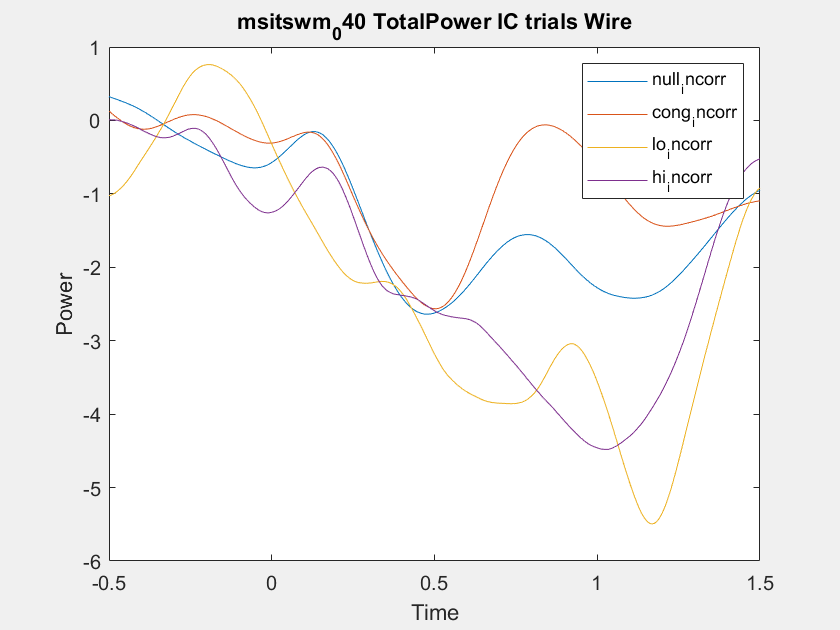

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


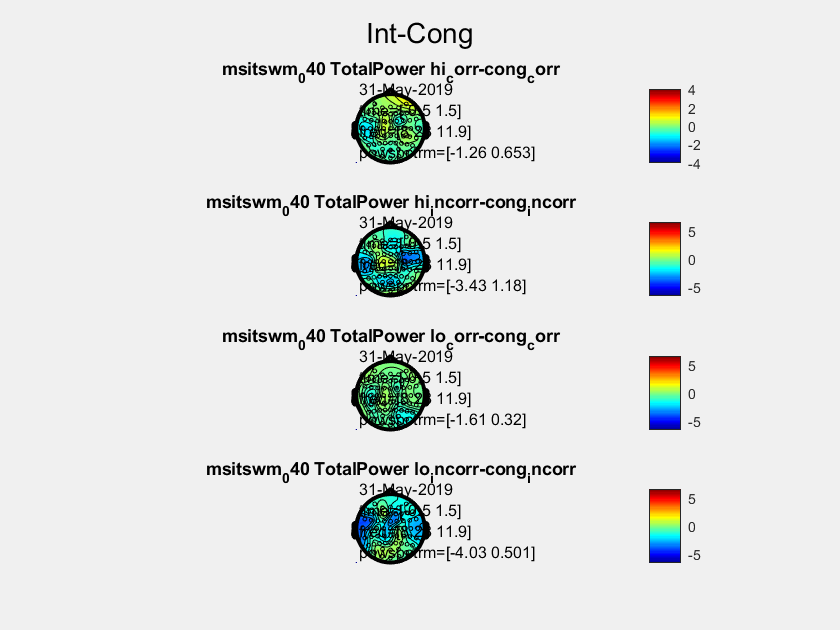

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


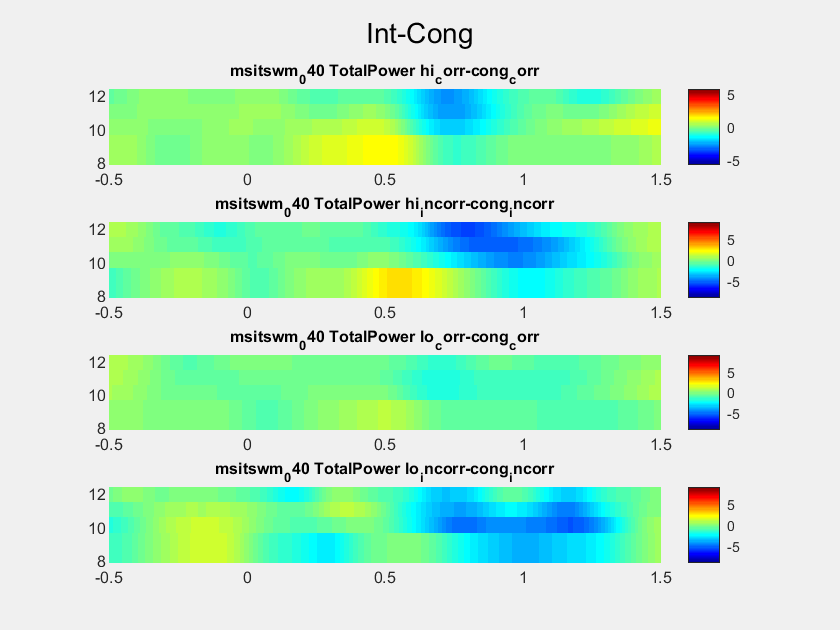

the call to "ft_singleplotTFR" took 0 seconds


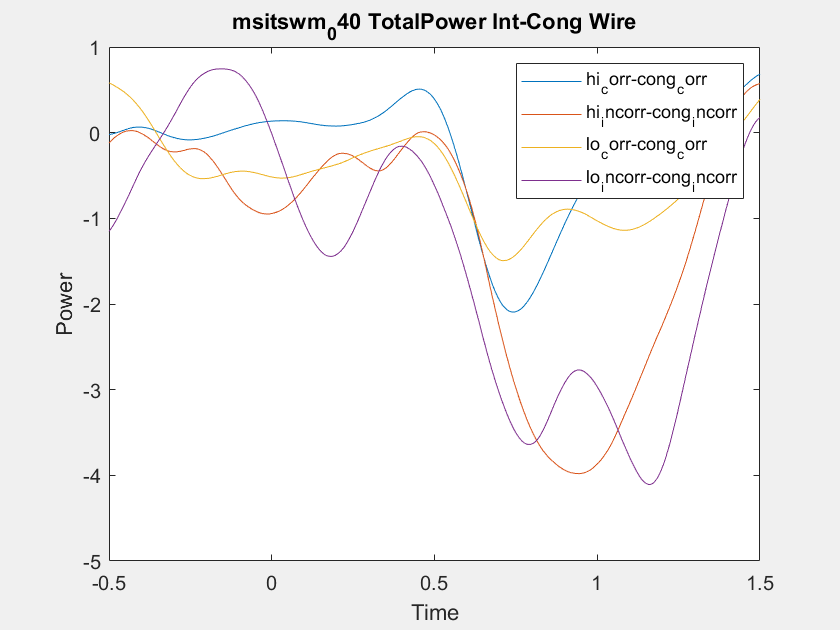

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


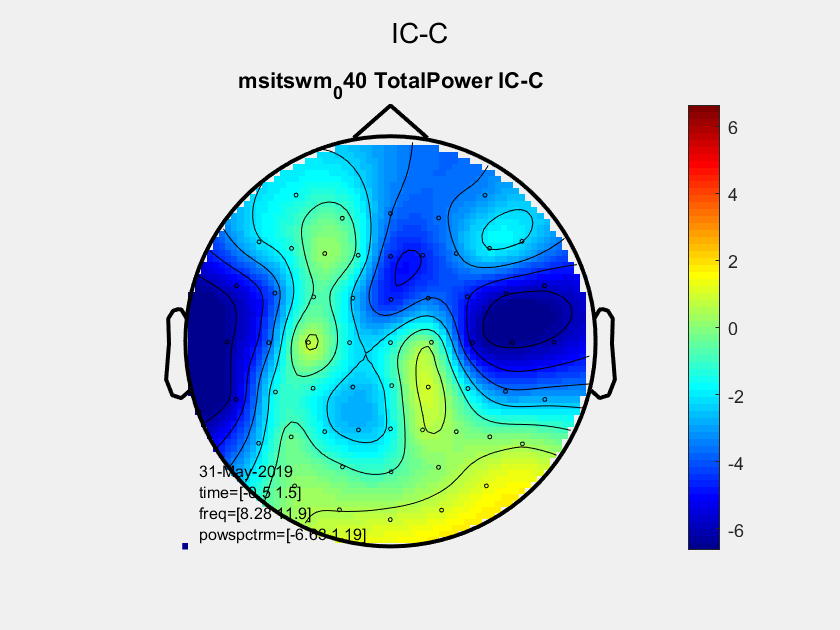

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


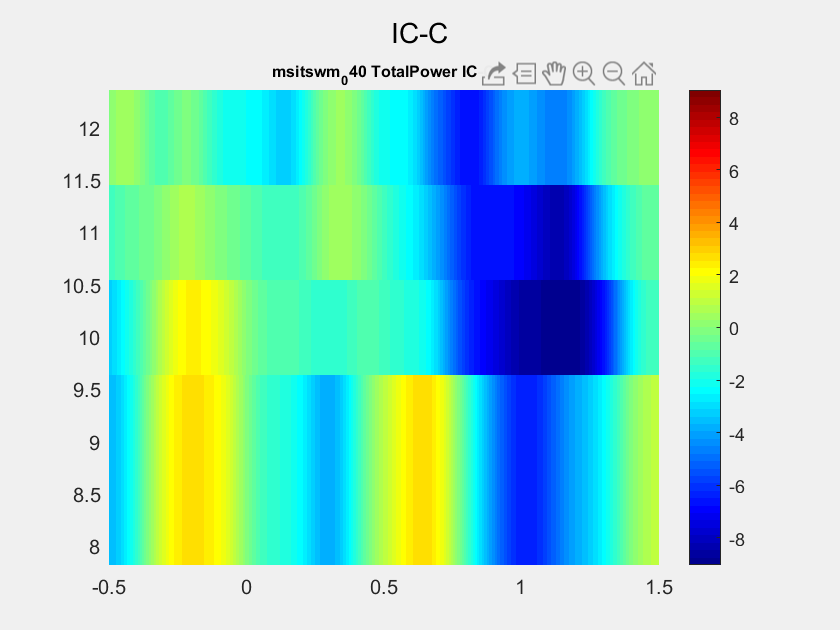

the call to "ft_singleplotTFR" took 0 seconds


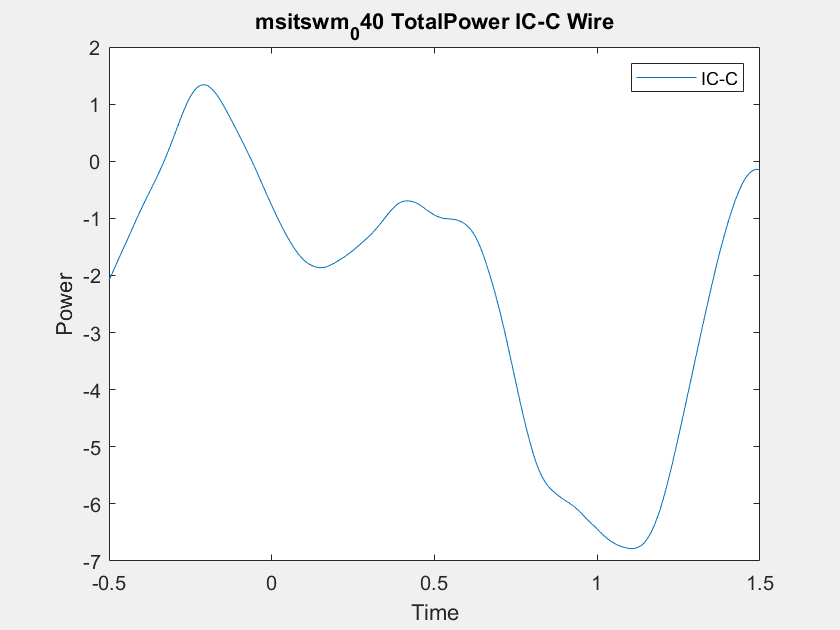

Deci_Backend(Deci);